# Basic Tight-Binding Theory - Part 1

## Introduction 

Tight-binding theory is used to describe the electronic structure of solids, particularly in crystalline materials. It is based on the assumption that electrons are strongly localized around atomic sites and can "hop" between neighboring atoms. The theory provides a simple yet powerful way to model the behavior of electrons in periodic potentials, such as those found in lattices of metals, semiconductors, and insulators. In second quantization, tight-binding theory gains a more comprehensive and flexible formulation; instead of dealing with wavefunctions (in the Hilbert space), second quantization uses creation and annihilation operators (in the Fock space) to describe the occupation of quantum states at each site. This formalism allows for an efficient representation of electronic interactions and hopping in lattice structures, providing deeper insight into the quantum mechanical properties of materials. The main goal of this educational project is to go through enough examples so that the reader may reach a better understanding of tight-binding theory and what it can do. 

## Formalism and definitions

Consider the one-body kinetic Hamiltonian


$$H = \sum_{ij} t_{ij} c_i^\dag c_j;\ t_{ij} = \langle i| H | j\rangle$$


where $i$ and $j$ represent the $i$th and $j$th atomic orbitals, and $t_{ij}$ is the hopping amplitude between said sites. This sum runs over all orbitals of all atomic sites that make up the lattice. We can break down the sum into two terms, one in which $i = j$ and the other one in which $i\neq j$. Now, $t_{ij}$ is essentially the energy required to place the electron at the $i$th site, hence, we'll define it as the "on-site" energy $u_i$. 


$$H = \sum_i u_i c_i^\dag c_i + \sum_{i\neq j} t_{ij} c_i^\dag c_j$$


Now, we can apply the **tight-binding approximation** to the second term in the Hamiltonian; nearest-neighbors (NN), and next-nearest-neighbors (NNN). 


$$t_{ij} =
\begin{cases}
    t_{ij}';\ \textit{$i$ and $j$ are NN}\\
    t_{ij}'';\ \textit{$i$ and $j$ are NNN}\\
    0:\ \textit{otherwise}
\end{cases}$$


Hence,


$$    H = \sum_i u_i c_i^\dag c_i + \sum_{\langle ij\rangle} t_{ij}' c_i^\dag c_j + \sum_{\langle\langle ij\rangle\rangle} t_{ij}'' c_i^\dag c_j$$


Where $\langle ij\rangle$ denote $i\neq j$, and $i$ and $j$ are NN, whereas $\langle\langle ij\rangle\rangle$ denote $i\neq j$, $i$ and $j$ are NNN (this part of the sum doesn't include NN hopping). To do a tight-binding calculation, we need to start off by defining the lattice structure of the system. Neglecting NNN hopping, we need only define the unit cell, and the primitive unit cell with its associated primitive lattice vectors $\mathbf{a}_1$, $\mathbf{a}_2$, and $\mathbf{a}_3$, then the coordinates of the atomic sites are defined. Furthermore, one may easily derive the reciprocal lattice vectors ($\mathbf{b}_1$, $\mathbf{b}_2$, and $\mathbf{b}_3$). 

## Example 1: The linear chain

Our first example will be the simplest, a one-dimensional linear chain of atoms with one orbital per site, and one site per unit cell. We first define the geometry of the system, starting off with the primitive vectors 


$$\mathbf{a_1} = (a,0,0)\Rightarrow\ \mathbf{b_1} = (2\pi/a, 0, 0)$$


The first Brillouin zone is $k_x\in [-\pi/a,\pi/a]$. 

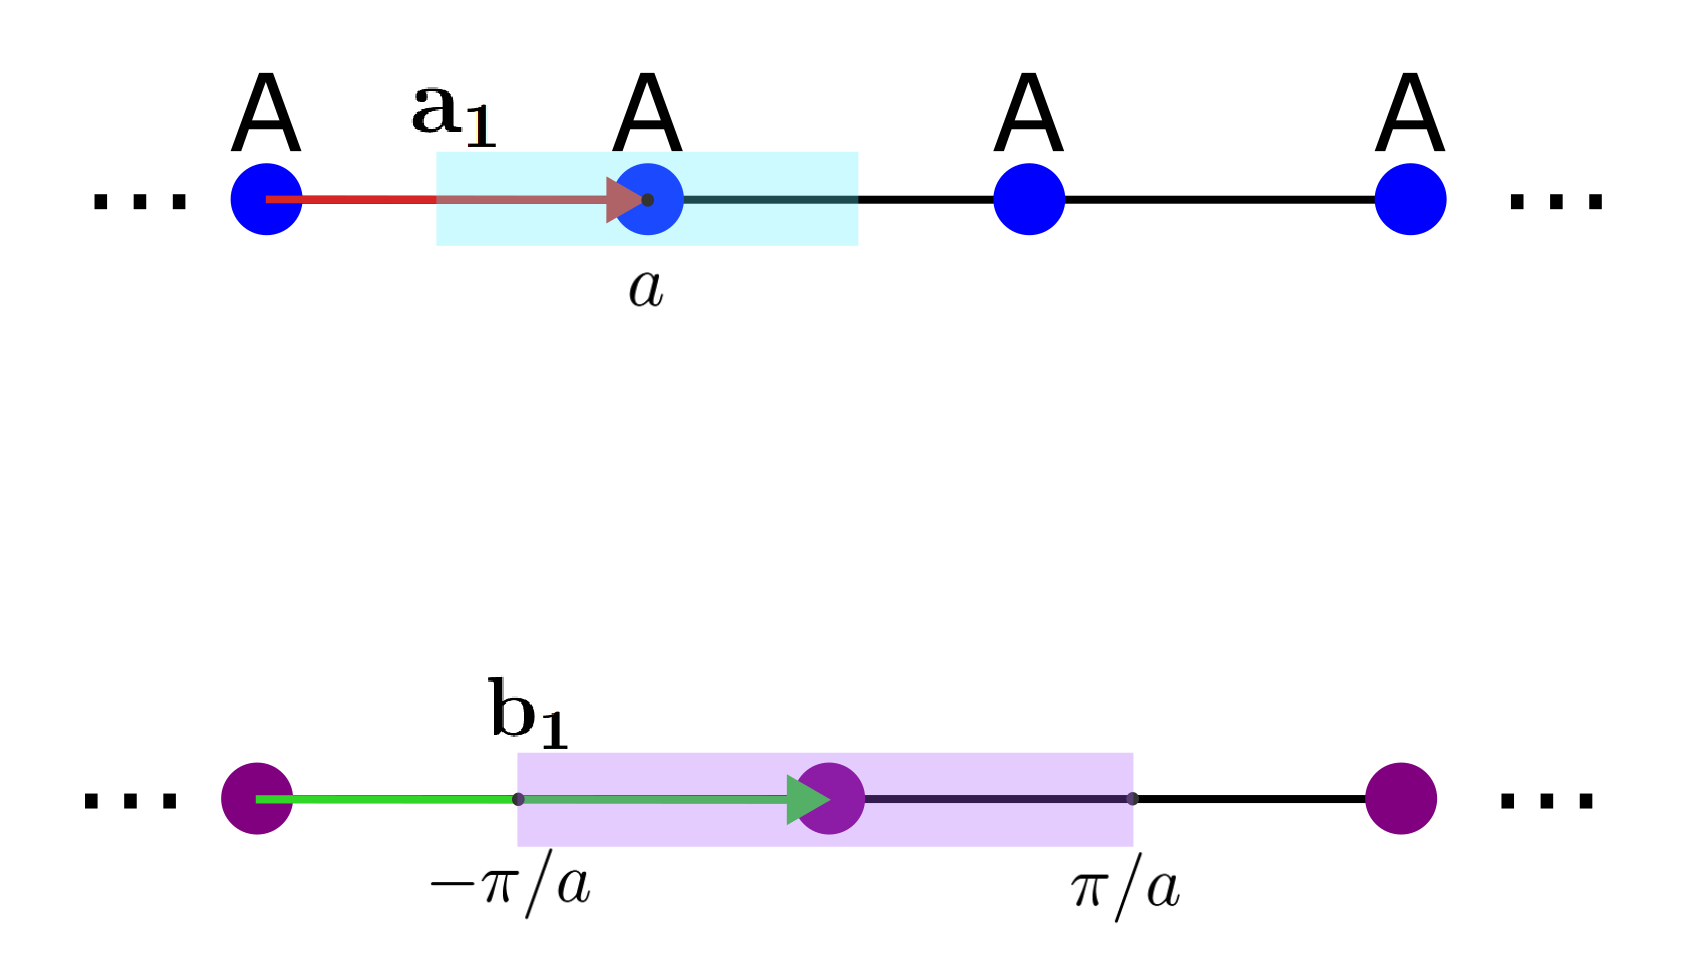

Next, we define the NN vectors $\mathbf{d}_n$: we may have $n$ NNs for a given site, in our case however, we only have two:


$$\mathbf{d}_1 = (a, 0, 0);\ \mathbf{d}_2 = (-a, 0, 0) = - \mathbf{d}_1$$


Considering fixed on-site and hopping energies (same atoms across), we can write the Hamiltonian as


$$H = u \sum_i c_i^\dag c_i + t \sum_{i, j} c_i^\dag c_j$$


For a change of basis $\{|u_i\rangle \rightarrow |v_j\rangle\}$, the following can be shown 

(i) Transformation rule - creation


$$a_{v_j}^\dag = \sum_i \langle u_i| v_j\rangle a_{u_i}^\dag$$


(ii) Transformation rule - annihilation


$$a_{v_j} = \sum_i \langle v_j| u_i\rangle a_{u_i}$$


We can use these transformation rules to express the state of a lattice in terms of the number of particles exhibiting different momenta $k$. Given that $\langle i | k\rangle = (1/\sqrt{N}) e^{i(\mathbf{k}\cdot \mathbf{r_i})}$, we have 


$$c_i =  \sum_k \langle i | k\rangle c_k = \frac{1}{\sqrt{N}} \sum_k e^{i(\mathbf{k}\cdot \mathbf{r_i})} c_k$$



$$ c_i^\dag =  \sum_k \langle k | i\rangle c_k^\dag = \frac{1}{\sqrt{N}} \sum_k e^{-i(\mathbf{k}\cdot \mathbf{r_i})} c_k^\dag$$


The following orthonormalities follow


$$ N \delta_{kk'} = \sum_i e^{\pm i (\mathbf{k} - \mathbf{k'})\cdot \mathbf{r_i}}$$



$$N \delta_{ij} = \sum_k e^{\pm i \mathbf{k}\cdot (\mathbf{r_i} - \mathbf{r_j})}$$


Changing basis to momentum space, we get


$$\[
H = u \sum_i \biggr[\frac{1}{\sqrt{N}} \sum_k e^{-i(\mathbf{k}\cdot \mathbf{r}_i)} c_k^\dag\biggr] \biggr[\frac{1}{\sqrt{N}} \sum_k e^{i(\mathbf{k}\cdot \mathbf{r}_i)} c_k\biggr] +\]
\[
t \sum_{i,j} \biggl\{\biggr[\frac{1}{\sqrt{N}} \sum_k e^{-i(\mathbf{k}\cdot \mathbf{r}_i)} c_k^\dag\biggr] \biggr[\frac{1}{\sqrt{N}} \sum_{k'} e^{i(\mathbf{k'}\cdot \mathbf{r}_j)} c_{k'}\biggr] + \biggr[\frac{1}{\sqrt{N}} \sum_{k'} e^{-i(\mathbf{k'}\cdot \mathbf{r}_j)} c_{k'}^\dag\biggr] \biggr[\frac{1}{\sqrt{N}} \sum_k e^{i(\mathbf{k}\cdot \mathbf{r}_i)} c_k\biggr]\biggl\}
\]
\[= \frac{u}{N} \sum_i (1) \sum_k  c_k^\dag c_k +\]
\[
\frac{t}{N}  \sum_k\sum_{k'} \sum_i \biggl\{ c_k^\dag c_{k'} e^{-i(\mathbf{k}\cdot \mathbf{r}_i)}  \biggr[\sum_j e^{i(\mathbf{k'}\cdot \mathbf{r}_j)}\biggr] +  c_{k'}^\dag c_k \biggr[\sum_j e^{-i(\mathbf{k'}\cdot \mathbf{r}_j)}\biggr] e^{i(\mathbf{k}\cdot \mathbf{r}_i)} \biggl\}
\]$$


Noting that $\sum_i (1) = N$, and inserting $1 = e^{-i(\mathbf{k'}\cdot \mathbf{r}_i)} e^{i(\mathbf{k'}\cdot \mathbf{r}_i)}$


$$\[
\Rightarrow H =  \sum_k  c_k^\dag u c_k + \frac{t}{N}  \sum_k\sum_{k'} \sum_i \biggl\{ c_k^\dag c_{k'} e^{i(\mathbf{k'}-\mathbf{k})\cdot \mathbf{r}_i}  \biggr[\sum_j e^{i\mathbf{k'}\cdot (\mathbf{r}_j-\mathbf{r}_i)}\biggr] +  c_{k'}^\dag c_k \biggr[\sum_j e^{-i\mathbf{k'}\cdot (\mathbf{r}_j-\mathbf{r}_i)}\biggr] e^{-i(\mathbf{k'}-\mathbf{k})\cdot \mathbf{r}_i} \biggl\}
\]$$


Applying the NN approximation: 


$$\sum_j e^{\pm i\mathbf{k'}\cdot (\mathbf{r}_j-\mathbf{r}_i)} = 
\begin{cases}
    \sum_{n=1}^2 e^{\pm i\mathbf{k'}\cdot \mathbf{d}_n};\ j\ \text{is a NN to}\ i\\
    0;\ \text{otherwise}
\end{cases}$$



$$\[
\Rightarrow H =  \sum_k  c_k^\dag u c_k + \frac{t}{N}  \sum_k\sum_{k'} \sum_i \biggl\{ c_k^\dag c_{k'} e^{-i(\mathbf{k'}-\mathbf{k})\cdot \mathbf{r}_i}  \biggr[\sum_{n=1}^2 e^{i\mathbf{k'}\cdot \mathbf{d}_n}\biggr] +  c_{k'}^\dag c_k \biggr[\sum_{n=1}^2 e^{- i\mathbf{k'}\cdot \mathbf{d}_n}\biggr] e^{i(\mathbf{k'}-\mathbf{k})\cdot \mathbf{r}_i} \biggl\}
\]
\[
=  \sum_k  c_k^\dag u c_k + \frac{t}{N}  \sum_k\sum_{k'}  \biggl\{ c_k^\dag c_{k'} \biggr[\sum_i e^{i(\mathbf{k'}-\mathbf{k})\cdot \mathbf{r}_i}\biggr]  \biggr[\sum_{n=1}^2 e^{i(\mathbf{k'}\cdot \mathbf{d}_n)}\biggr] +  c_{k'}^\dag c_k \biggr[\sum_{n=1}^2 e^{i(\mathbf{k'}\cdot \mathbf{d}_n)}\biggr]^* \biggr[\sum_i e^{-i(\mathbf{k'}-\mathbf{k})\cdot \mathbf{r}_i}\biggr] \biggl\}
\]$$


Using the orthonormality relation, and defining $f(\mathbf{k})$, we get


$$\[
H = \sum_k  c_k^\dag u c_k + \frac{t}{N}  \sum_k\sum_{k'}  \biggl\{ c_k^\dag c_{k'} \bigr[N\delta_{kk'}\bigr]  \bigr[f(\mathbf{k'})\bigr] +  c_{k'}^\dag c_k \bigr[f^*(\mathbf{k'})\bigr] \bigr[N\delta_{kk'}\bigr] \biggl\}
\]$$


Also note that $f(\mathbf{k})\in\mathbb{R}$: 


$$\[f(\mathbf{k}) = \sum_{n=1}^2 e^{i(\mathbf{k}\cdot \mathbf{d}_n)} = e^{i(\mathbf{k}\cdot \mathbf{d}_1)} + e^{i(\mathbf{k}\cdot \mathbf{d}_2)} = e^{i(\mathbf{k}\cdot \mathbf{d}_1)} + e^{-i(\mathbf{k}\cdot \mathbf{d}_1)} = 2 \cos(\mathbf{k}\cdot\mathbf{d}_1)\]$$



$$\[\Rightarrow f(\mathbf{k}) = f^*(\mathbf{k})\]

\[
\Rightarrow H = \sum_k  c_k^\dag u c_k + t  \sum_k  \biggr[ c_k^\dag c_{k} f(\mathbf{k}) +  c_{k}^\dag c_k f(\mathbf{k}) \biggr]
= \sum_k  c_k^\dag u c_k +  \sum_k  c_k^\dag 2 t f(\mathbf{k}) c_{k} 
\]
\[
= \sum_k  c_k^\dag [u + 2 t f(\mathbf{k})] c_k
\]$$


Let us also define the Hamiltonian in k-space $\tilde{H} \equiv u + t f(\mathbf{k})$. In our case, the matrix $\tilde{H}$ is a one-by-one matrix, hence, the eigenvalue of such a matrix will be the matrix itself. 


$$\[
\det[\tilde{H} - \mathbb{1} E ] = 0 = \det[u+t f(\mathbf{k})- E ] = u+t f(\mathbf{k}) - E = 0
\]
\[
\therefore E(\mathbf{k}) = u+t f(\mathbf{k}) = u + 2 t \cos(\mathbf{k}\cdot \mathbf{d_1}) = u + 2 t \cos(k_x a)
\]$$


Plotting the band structure is a really simple task:

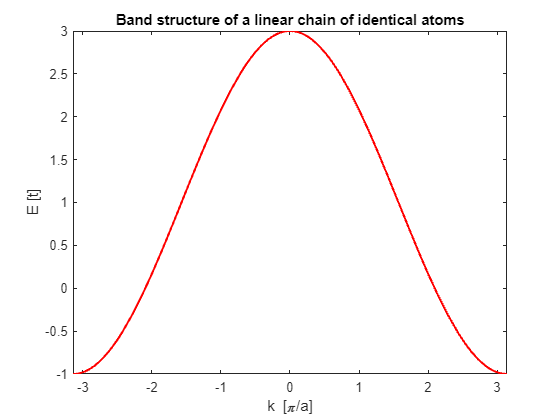

% Define the parameters
u = 1; % units of t

% Define the eigen - energy as a function of ka
E = @( ka ) 1 + 2* cos ( ka ); % In units of t

% Plot the eigen-energy function
fplot (E ,[ - pi , pi ] , 'r ' , LineWidth =1.5);
xlabel ("k [\pi/a]");
ylabel ("E [t]");
title('Band structure of a linear chain of identical atoms');

For the linear chain with two sites per unit cell, i.e., (...-A-B-A-B-A-B-...). The geometry (primitive vectors and NN vectors) will obviously be the same as the linear chain of identical atoms. However, the Hamiltonian will change accordingly.

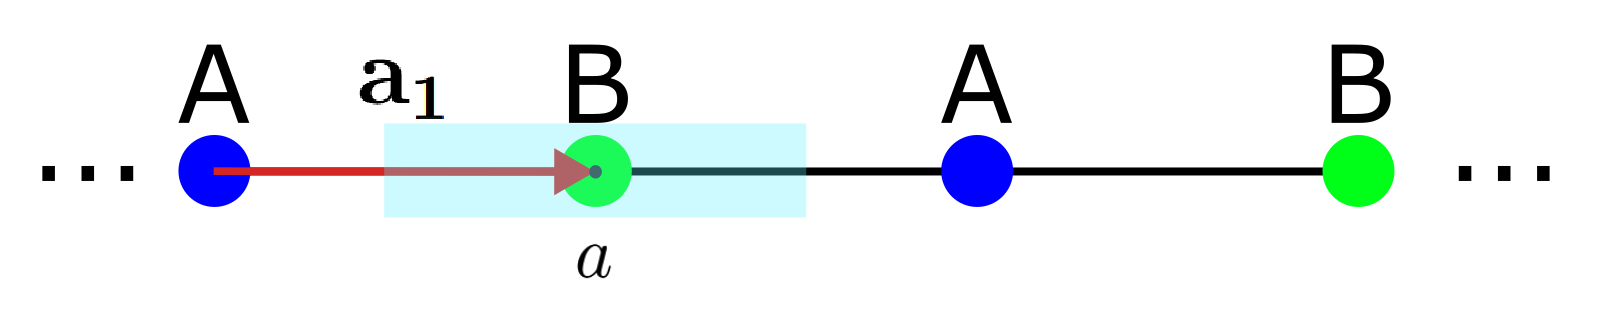


$$H = u_A \sum_i a_i^\dag a_i + u_B \sum_j b_j^\dag b_j + t \sum_{i, j} (a_i^\dag b_j+ b_j^\dag a_i)$$


Also note that


$$t \sum_{i, j} a_i^\dag b_j+ \textbf{h.c.} = t \sum_{i, j} a_i^\dag b_j + \biggl(t \sum_{i, j} a_i^\dag b_j\biggl)^\dag = t \sum_{i, j} a_i^\dag b_j + t \sum_{i, j} (a_i^\dag b_j)^\dag = t \sum_{i, j} a_i^\dag b_j + t \sum_{i, j} b_j^\dag a_i 
= t \sum_{i, j} (a_i^\dag b_j+ b_j^\dag a_i)
$$


Hence, using the "$\mathbf{h.c.}$" notation, changing basis to $k
$-space, and setting $u_A = u_B = u$ we get


$$\[
H = \sum_i u_i \biggr[\frac{1}{\sqrt{N}} \sum_k e^{-i(\mathbf{k}\cdot \mathbf{r}_i)} a_k^\dag\biggr] \biggr[\frac{1}{\sqrt{N}} \sum_k e^{i(\mathbf{k}\cdot \mathbf{r}_i)} a_k\biggr] + 

\sum_j u_j \biggr[\frac{1}{\sqrt{N}} \sum_{k'} e^{-i(\mathbf{k'}\cdot \mathbf{r}_j)} b_{k'}^\dag\biggr] \biggr[\frac{1}{\sqrt{N}} \sum_{k'} e^{i(\mathbf{k'}\cdot \mathbf{r}_j)} b_{k'}\biggr] + 
t \sum_{i, j} \biggl\{\biggr[\frac{1}{\sqrt{N}} \sum_k e^{-i(\mathbf{k}\cdot \mathbf{r}_i)} a_k^\dag\biggr] \biggr[\frac{1}{\sqrt{N}} \sum_{k'} e^{i(\mathbf{k'}\cdot \mathbf{r}_j)} b_{k'}\biggr]+ \textbf{h.c.}\biggl\}
\]

\[
= \sum_k  a_k^\dag u a_k + \sum_{k'}  b_{k'}^\dag u b_{k'} +
\frac{t}{N} \sum_{i, j} \biggr[\sum_k \sum_{k'} e^{-i(\mathbf{k}\cdot \mathbf{r}_i)} a_k^\dag e^{i(\mathbf{k'}\cdot \mathbf{r}_j)} b_{k'}+ \textbf{h.c.}\biggr]
\]$$


We can re-index the second term since $k$ and $k'$ are not coupled in that sum.


$$\[
H= \sum_k  a_k^\dag u a_k + \sum_{k}  b_{k}^\dag u b_{k} +
\frac{t}{N} \sum_{k, k'} \biggr[a_k^\dag b_{k'} \sum_i e^{-i(\mathbf{k}\cdot \mathbf{r}_i)} \sum_{j}  e^{i(\mathbf{k'}\cdot \mathbf{r}_j)} + \textbf{h.c.} \biggr]
\]$$


Inserting $1 = e^{-i(\mathbf{k'}\cdot \mathbf{r}_i)} e^{i(\mathbf{k'}\cdot \mathbf{r}_i)}$, we have


$$\[
H = \sum_k  a_k^\dag u a_k + \sum_{k}  b_{k}^\dag u b_{k} + \frac{t}{N} \sum_{k, k'} \biggr[a_k^\dag b_{k'} \sum_i e^{i(\mathbf{k'}-\mathbf{k})\cdot \mathbf{r}_i} \biggr[\sum_{j}  e^{i\mathbf{k'}\cdot (\mathbf{r}_j-\mathbf{r}_i)}\biggr] + \textbf{h.c.} \biggl\}
\]$$


Applying the NN approximation, we get


$$

\[
H = \sum_k  a_k^\dag u a_k + \sum_{k}  b_{k}^\dag u b_{k} + \frac{t}{N} \sum_{k, k'} \biggl\{a_k^\dag b_{k'} \biggr[\sum_i e^{-i(\mathbf{k'}-\mathbf{k})\cdot \mathbf{r}_i}\biggr] f(\mathbf{k'}) + \textbf{h.c.} \biggl\}
\]

\[
= \sum_k  a_k^\dag u a_k + \sum_{k}  b_{k}^\dag u b_{k} + \frac{t}{N} \sum_{k, k'} \biggr[a_k^\dag b_{k'} N\delta_{kk'} f(\mathbf{k'}) + \textbf{h.c.} \biggr]
\]

\[
= \sum_k  a_k^\dag u a_k + \sum_{k}  b_{k}^\dag u b_{k} + t \sum_{k} \biggr[a_k^\dag b_{k} f(\mathbf{k}) + \textbf{h.c.} \biggr]
\]

\[
= \sum_k \biggr[a_k^\dag u a_k + b_{k}^\dag u b_{k} + a_k^\dag t f(\mathbf{k}) b_{k}+ b_{k}^\dag t f^*(\mathbf{k}) a_k\biggr] 
\]
\[
= \sum_k 
\left(
\begin{array}{c c}
a_k^\dag & b_k^\dag
\end{array}
\right)
\left(
\begin{array}{c c}
    u & t f(\mathbf{k})\\
    t f^*(\mathbf{k}) & u
\end{array}
\right)
\left(
\begin{array}{c}
a_k \\ b_k
\end{array}
\right)
\]$$


Evidently, the Hamiltonian in k-space is


$$\[
\tilde{H} \equiv 
\left(
\begin{array}{c c}
    u & t f(\mathbf{k})\\
    t f^*(\mathbf{k}) & u
\end{array}
\right)
;\ |\Psi_k\rangle:= 
\left(
\begin{array}{c}
a_k\\
b_k
\end{array}
\right)
\]$$



$$\[\Rightarrow \det(\tilde{H} - \mathbb{I}E) = 0 = 
\det\left(
\begin{array}{cc}
    u-E & t f(\mathbf{k})\\
    t f^*(\mathbf{k}) & u-E
\end{array}
\right)
= (E-u)^2 - t^2 |{f(\mathbf{k})}|^2 = (E-u)^2 - t^2 \biggl|e^{i\mathbf{k'}\cdot \mathbf{d}_1} + e^{i\mathbf{k'}\cdot \mathbf{d}_2}\biggl|^2
\]
\[
= (E-u)^2 - t^2 \biggl|e^{i\mathbf{k'}\cdot \mathbf{d}_1} + e^{-i\mathbf{k'}\cdot \mathbf{d}_1}\biggl|^2 = (E-u)^2 - t^2 |2\cos{(\mathbf{k}\cdot\mathbf{d}_1)}|^2 = (E-u)^2 - 4 t^2 \cos^2{(k_x a)} = 0
\]
\[
\therefore E(\mathbf{k}) = u\pm 2 t \cos{(k_x a)} 
\]$$


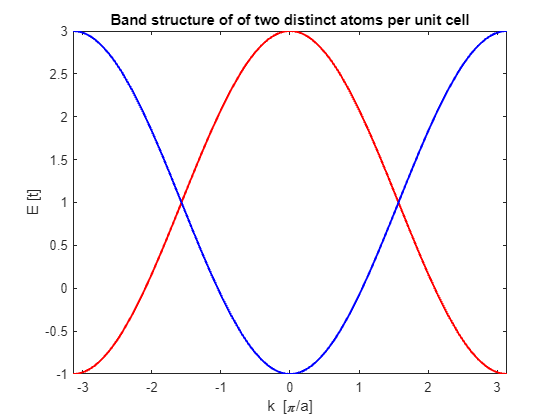

% Define the parameters 
u = 1; % units of t

% Define the eigen-energy as a function of ka 
E1 = @(ka) 1 + 2*cos(ka); % In units of t
E2 = @(ka) 1 - 2*cos(ka); % In units of t

% Plot the eigen-energy function 
fplot(E1,[-pi, pi], 'r', LineWidth=1.5)
hold on
fplot(E2,[-pi, pi], 'b', LineWidth=1.5)
xlabel ("k [\pi/a]")
ylabel ("E [t]")
title('Band structure of of two distinct atoms per unit cell')
hold off